clear
hold on
class=[15, 25, 55, 115,144, 242]

class =     15    25    55   115   144   242


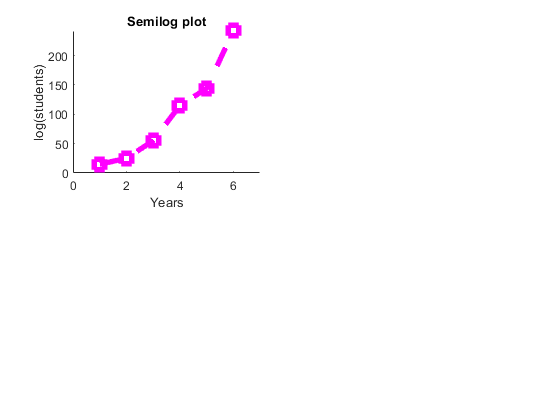

semilogy(class,'m--s',"LineWidth",4,"MarkerSize",10)
xlim([0 7])
title('Semilog plot')
xlabel('Years')
ylabel('log(students)')
hold off

load mitMap.mat
subplot(2,2,1)
hold on 

image(mit)

Unrecognized function or variable 'mit'.

colormap(cMap)
axis('square')
title('Square')
hold off
subplot(2,2,2)
hold on
image(mit)
colormap(cMap)
axis('tight')
title('Tight')
hold off
subplot(2,2,3)
hold on
image(mit)
colormap(cMap)
axis('equal')
title('Equal')
hold off
subplot(2,2,4)
hold on
image(mit)
colormap(cMap)
axis('xy')
title('XY')

clear
z=rand(1,5)
bar(z,'red')

z0=rand(5)
[x0,y0]=meshgrid([1:5],[1:5])

[x1,y1]=meshgrid([1:0.1:5],[1:0.1:5])

z1=interp2(x0,y0,z0,x1,y1,"cubic")
surf(z1)
colormap("hsv")
shading("interp")
hold on
contour(z1)
colorbar
caxis([0 1])

load noisyData.mat
d=x
plot(x,'.b',"MarkerSize",8)
width=5;
hold on
smoothed=[];
if (width==5)
for n=3:98
    smoothed(n)=mean(x(n-2 : n+2));
end
        smoothed(1)=x(1);
        smoothed(2)=mean(x(1:3));
        smoothed(100)=x(100);
        smoothed(99)=mean(x(98:100));
end
plot(smoothed,'r')







